 clear
 clc

%Set Values
ChordD_data = struct2array(load('ChordD.mat'));
TwistA_data = struct2array(load('TwistA.mat'));
% ChordD_data(2,:) = (atand(Diameter./(3.55*(linspace(0.035,0.25,100)).^1.06*ratiolam))-DesAlph); 
% TwistA_data(2,:) = (((16*pi*linspace(0.035,0.25,100))/(N*LiftC)).*sin((1/3)*atan(Diameter./(2*R*ratiolam))).^2);
 FreeNormVel = 10; % The velocity of wind tunnel (m/s)
 N = 2; % Number Of fans
 row = 1.204;
 kVisc = 1.506e-5;
 Diameter = 0.5;
 slices = 100;
 Mach = 30/343;
 Ncrit = 5;
 aopt = 1/3;
 RootStart = 0.035;
 adashopt = 0.02;
 Constant = (1/2)*row*pi*((Diameter/2)^2)*(10^3)

Constant = 118.2024

 
 ReInit = [59000,57000]

ReInit =        59000       57000


 AirfoilChangeR = Diameter/8; %Turn into an array if more than one change

 % for i = 1:(length(AirfoilChangeR)+1)
 %      [XFOILA1,DesAlpha(i)] = run_xfoil(SG60(:,((i*2)-1):(i*2)), ReInit(i), Mach, Ncrit, min(alpha_grid), max(alpha_grid)); %Idk why warning it seems to work 
 %  %Calculated from XFOIL data
 %   ForTwstGrphAlpha = DesAlpha;
 %  [~,idx] = min(abs(XFOILA1(:,1)-DesAlpha(i)));
 %  LiftCoef(i) = XFOILA1(idx,2);
 %  end

% ONLY RUN THIS ONCE

 % Sample airfoil coordinates (x, y)
SG60(:,1:2) = table2array(readtable('SG6040cords.csv','PreserveVariableNames',true));
SG60(:,3:4) = table2array(readtable('SG6043cords.csv','PreserveVariableNames',true));

% Example ranges
Re_grid = logspace(4.3, 5.05, 10);        % 10 values 
alpha_grid = linspace(-10, 35, 40);  % -10 to 20 degrees
DesAlpha_table = zeros((length(AirfoilChangeR)+1), length(Re_grid));
for i = 1:(length(AirfoilChangeR)+1)
     [XFOILA1,DesAlpha(i)] = run_xfoil(SG60(:,((i*2)-1):(i*2)), ReInit(i), Mach, Ncrit, min(alpha_grid), max(alpha_grid)); %Idk why warning it seems to work 
 %Calculated from XFOIL data
 ForTwstGrphAlpha = DesAlpha;
 [~,idx] = min(abs(XFOILA1(:,1)-DesAlpha(i)));
 LiftCoef(i) = XFOILA1(idx,2);
    for j = 1:length(Re_grid)
        [XFOIL, ~] = run_xfoil(SG60(:,((i*2)-1):(i*2)), Re_grid(j), Mach, Ncrit, min(alpha_grid), max(alpha_grid));
        % XFOIL(:,1) = alpha, XFOIL(:,2) = CL, XFOIL(:,3) = CD
        CL = XFOIL(:,2);
        CD = XFOIL(:,3);
        CLCD = CL ./ CD;
        [~, idx_max] = max(CLCD);
        DesAlpha_table(i, j) = XFOIL(idx_max, 1); % Store optimum alpha for this Re
        % (Also fill CL_table and CD_table as before)
        for k = 1:length(alpha_grid)
            idx = find(abs(XFOIL(:,1)-alpha_grid(k)) == min(abs(XFOIL(:,1)-alpha_grid(k))), 1);
            CL_table(i,j,k) = XFOIL(idx,2);
            CD_table(i,j,k) = XFOIL(idx,3);
        end
    end
end

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

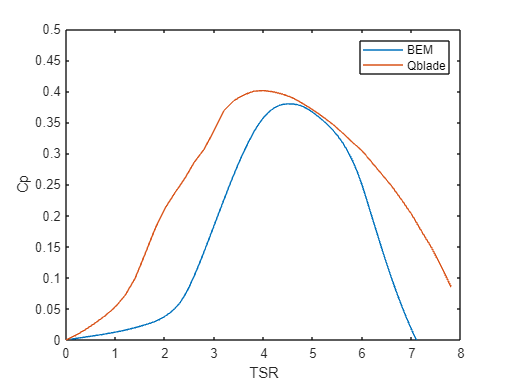

%Using slides (lubbock) method] (Only uses sg43 airfoil rn)
%Seems to scale wierdly with lambda
Wlist=zeros(91,slices); %added this (lothaire)
philist = zeros(91, slices); %added this (lothaire) just to store values
storePw = zeros(1,91);
storea = zeros(91,slices);
storealpha = zeros(91,slices);
figure
% for ratiolam = 4:0.1:6
TwistInterp = griddedInterpolant(TwistA_data(1,:), TwistA_data(2,:), 'linear', 'nearest');
ChordInterp = griddedInterpolant(ChordD_data(1,:), ChordD_data(2,:), 'linear', 'nearest');
Qbladeresults = table2array(readtable('TSSSR.csv','PreserveVariableNames',true));


TwistEquation = @(R,~) TwistInterp(R);
ChordEquation = @(R,~) ChordInterp(R);  % LiftC is unused now
for ratiolambda = 0.1:0.1:9.1
    alist = [];
    alphalist = [];
    ReList = [];
angvel = (ratiolambda*FreeNormVel)/(Diameter/2);
fn=0;
Pw = 0;
Torque = 0;
Wtot = 0;

for R = linspace(RootStart,(Diameter/2),slices)
i = find(R <= AirfoilChangeR, 1); if isempty(i), i = length(AirfoilChangeR)+1; end
a = aopt;
adash = adashopt;
phi = (atand((1-a)*Diameter/(2*ratiolambda*R*(1+adash))));
phi1 = phi + 10; 
brnum = 0 ;
while abs(phi - phi1) > 0.001
    brnum = brnum+1;
Alpha = (-(TwistEquation(R,DesAlpha(i)) - phi));
W = sqrt(((angvel*R)^2)+(FreeNormVel*(1-a))^2);
Re(i) = ((W*ChordEquation(R,LiftCoef(i)))/kVisc);
% DesAlpha(i) = interp1(Re_grid, DesAlpha_table(i,:), Re(i), 'linear', 'extrap');

% Extract the 2D slices from CL_table and CD_table
cl_slice = squeeze(CL_table(i,:,:));
cd_slice = squeeze(CD_table(i,:,:));

% Transpose if needed to match grid dimensions
if size(cl_slice,1) ~= length(alpha_grid)
    cl_slice = cl_slice.';
    cd_slice = cd_slice.';
end


% Create interpolants with extrapolation
% Replace current interpolants with safer ones
liftInterp = griddedInterpolant({alpha_grid, Re_grid}, cl_slice, 'linear', 'linear');
liftInterp.ExtrapolationMethod = 'linear';

dragInterp = griddedInterpolant({alpha_grid, Re_grid}, cd_slice, 'linear', 'linear');
dragInterp.ExtrapolationMethod = 'linear';


% Interpolate lift and drag coefficients
CL = liftInterp(Alpha, Re(i));
CD = dragInterp(Alpha, Re(i));

% Store coefficients
LiftCoef(length(AirfoilChangeR)+2) = CL;
DragCoef(length(AirfoilChangeR)+2) = CD;


% to use the stall correction function, we would probably also need an
% array of Cd0 and AOA0 for the arifoils, these are the final two inputs in the equation
% [LiftCoef(length(AirfoilChangeR)+2),DragCoef(length(AirfoilChangeR)+2)] =
% stall_corrected(XFOIL(idx2,(2+3*(i-1))),XFOIL(idx2,(3+3*(i-1))),Alpha,(R/(Diameter/2)),ChordEquation(R,LiftCoef(i)),angvel,0.04125,-1); 
a_new = ratiolambda*(LiftCoef(length(AirfoilChangeR)+2)*N*ChordEquation(R,LiftCoef(i)))/(Diameter*pi*4*sind(phi));
a = 0.7*a + 0.3*a_new;  % Smooth update

adash_new = 1/(((2*pi*4*sind(phi)*cosd(phi))/(LiftCoef(length(AirfoilChangeR)+2)*N*ChordEquation(R,LiftCoef(i)))) - 1);
adash = 0.7*adash + 0.3*adash_new;  % Smooth update
a = min(max(a, 0), 0.95);        % Clamp a to [0, 0.95]
adash = min(max(adash, 0), 0.95);  % Clamp adash similarly
phi1 = phi;
phi_new = atand((1-a)*Diameter/(2*ratiolambda*R*(1+adash)));
phi = 0.5*phi + 0.5*phi_new;
if brnum == 10
    break
end
end
alphalist = [alphalist,Alpha];
alist = [alist,a];
W = sqrt(((angvel*R)^2)+(FreeNormVel*(1-a))^2);
ReList = [ReList,((W*ChordEquation(R,LiftCoef(i)))/kVisc)];
% Wlist(round((ratiolambda-1)/0.1)+1, round((R - RootStart)/((Diameter/2 - RootStart)/(slices-1))) + 1) = W; %added this (lothaire) just to store values
% philist(round((ratiolambda-1)/0.1)+1, round((R - RootStart)/((Diameter/2 - RootStart)/(slices-1))) + 1) = phi; %added this (lothaire) just to store values
Wtot = Wtot+W;
Ftip = (2/pi)*acos(exp(-(N/2)*(((Diameter/2)-R)/(R*sind(phi))))); %Prandtls tip loss
Froot = (2/pi)*acos(exp(-(N/2)*((R-(RootStart))/(R*sind(phi))))); %Prandtls root loss
Ftotal = Ftip*Froot; %total tip and root corrections
dR = ((Diameter/2)-(RootStart))/slices;
ForceTot = N * 0.5 * row * W^2 * ChordEquation(R,LiftCoef(i)) * (LiftCoef(length(AirfoilChangeR)+2)*sind(phi)-DragCoef(length(AirfoilChangeR)+2)*cosd(phi));
dPw = (ForceTot * R - 0.03) * angvel * dR; %0.03 accounts for motor resistance
Pw = Pw + dPw*Ftotal;
Torque = Torque + (ForceTot * R - 0.03) * dR*Ftotal;

end
storePw(int32(ratiolambda*10)) = Pw;
storeTorque(int32(ratiolambda*10)) = Torque;
storea(int32(ratiolambda*10),:) = alist;
storealpha(int32(ratiolambda*10),:) = alphalist;
storeRe(int32(ratiolambda*10),:) = ReList;
StoreW(int32(ratiolambda*10)) = Wtot/slices;
end
[val, optlambda] = max(storePw);
plot(0.1:0.1:9.1,storePw/Constant)
ylim([0,0.5])
% title('Cp Vs TSR for given twist and chord');
xlabel('TSR');
ylabel('Cp')
hold on
plot(Qbladeresults(:,1),Qbladeresults(:,2))
% end
hold off
legend('BEM','Qblade')

% legend('4.0','4.1','4.2','4.3','4.4','4.5','4.6','4.7','4.8','4.9','5.0','5.1','5.2','5.3','5.4','5.5','5.6','5.7','5.8','5.9','6.0')
MaxPower = storePw(optlambda)

MaxPower = 44.8698

MaxCp = MaxPower/Constant

MaxCp = 0.3796

storeRe(optlambda,:)

ans = 1.0e+05 *

    0.6215    0.6324    0.6423    0.6516    0.6605    0.6688    0.6764    0.6833    0.6898    0.6958    0.7012    0.7058    0.7090    0.6596    0.6661    0.6729    0.6797    0.6866    0.6934    0.7001    0.7068    0.7135    0.7200    0.7265    0.7330    0.7393    0.7457    0.7519    0.7581    0.7642    0.7703    0.7763    0.7822    0.7881    0.7941    0.8000    0.8060    0.8119    0.8177    0.8235    0.8293    0.8351    0.8409    0.8466    0.8523    0.8580    0.8637    0.8693    0.8749    0.8805


mean(storeRe(optlambda,1:37))

ans = 7.1278e+04

mean(storeRe(optlambda,38:end))

ans = 9.8385e+04

storealpha(optlambda,:)

ans =    24.7069   24.4146   24.0743   23.7006   23.2959   22.8647   22.3907   21.8937   21.3693   20.8263   20.2200   19.5526   18.7828   14.6327   14.1239   13.6677   13.2316   12.8423   12.4714   12.1112   11.7701   11.4539   11.1480   10.8522   10.5691   10.3005   10.0420    9.7918    9.5496    9.3105    9.0781    8.8517    8.6313    8.4168    8.2184    8.0355    7.8626    7.6966    7.5365    7.3811    7.2306    7.0877    6.9513    6.8194    6.6914    6.5664    6.4440    6.3246    6.2073    6.0925


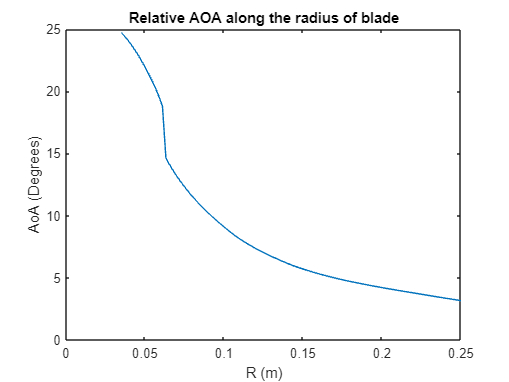

% storea(optlambda,:) %Array of a at optimum TSR
% StoreW(optlambda) %AvgVelociity
figure
plot(linspace(RootStart,Diameter/2,slices),storealpha(optlambda,:))
title('Relative AOA along the radius of blade');
xlabel('R (m)');
ylabel('AoA (Degrees)')

optlambda = (optlambda)/10

optlambda = 4.5000

StartingTorque = storeTorque(2)

StartingTorque = 0.0376

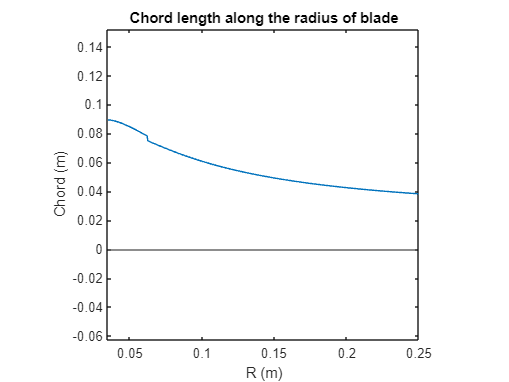

% % NEW METHOD
figure
plot(ChordD_data(1,:),ChordD_data(2,:))
title('Chord length along the radius of blade');
xlabel('R (m)');
ylabel('Chord (m)')
yline(0)
set(gca,'DataAspectRatio',[1 1 1],'PlotBoxAspectRatio',[1 1 1],'XLim',[RootStart,(Diameter/2)])
hold off

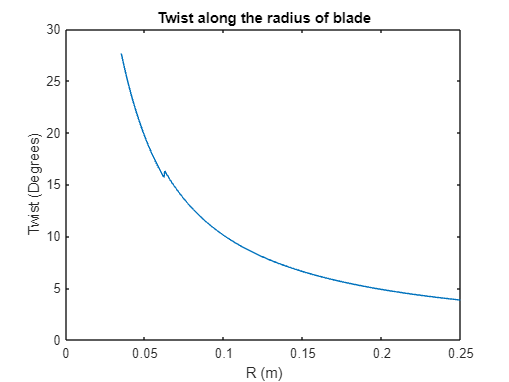


figure
plot(TwistA_data(1,:),TwistA_data(2,:))
title('Twist along the radius of blade');
xlabel('R (m)');
ylabel('Twist (Degrees)')
yline(0)
% set(gca,'DataAspectRatio',[1 1 1],'PlotBoxAspectRatio',[1 1 1],'XLim',[RootStart,(Diameter/2)])
hold off

% % LUBBOCK METHOD
% % To find chord distribution
% AreaBlade = (((Diameter/2)^2)/(N*ratiolambda))
% ChordIntegral = @(k) (integral(@(x) (k./x),(Diameter/20),(Diameter/2))-AreaBlade)
% k = fzero(ChordIntegral,0.1)
% ChordEquation = @(R) (k./R)
% plot(r,ChordEquation(r))
% yline(0)
% set(gca,'DataAspectRatio',[1 1 1],'PlotBoxAspectRatio',[1 1 1],'XLim',[Diameter/20,(Diameter/2)])
% hold off

% % To find twist
% figure
% for i = 1:2
% TwistEquation = @(R) (atand(Diameter./(3*R*ratiolambda))-DesAlpha(i));
% plot(r(i,:),TwistEquation(r(i,:)))
% hold on
% end
% yline(0)
% hold off

% FOR WHATEVER REASON THIS CODE USING I2A IS WRONG (IDK WHY)
% boundr(1:2) = [(Diameter/2),(Diameter/20)];
% for i = 1:2
% ChordEquation = @(R) (((16*pi*R)/(N*LiftCoef(i))).*sin((1/3)*atan(Diameter./(2*R*ratiolambda))).^2); %try to remove later for ease of code
% Fn(i) = 0; %Found iteratively, Loop till convergence
%  Fn1(i) = 10;
% while abs(Fn(i) - Fn1(i)) > 0.00001
%  angvel = (ratiolambda*FreeNormVel)/(Diameter/2);
%  NormVel = (FreeNormVel/2) - (1/2)*sqrt((FreeNormVel^2) + (8*Fn(i))/(row*pi*Diameter^2)); %the second part applies the induced stuff
%  TangVel = @(x) (angvel*x); %func of R
%  TotalVel =  @(x) (sqrt((x.^2)+NormVel^2)); %func of TangVel
%  dAOA =  @(x) (atand(NormVel./x)); %func of TangVel
% 
%  SingleIntegral = @(a,b,c) (1/2*row*(a.^2).*c.*(LiftCoef(i)*cosd(b)+(sind(b)*DragCoef(i))));
%  Fn1(i) = Fn(i);
%  Fn(i) = (N)*integral(@(x) SingleIntegral(TotalVel(TangVel(x)),dAOA(TangVel(x)),ChordEquation(x)),(Diameter/8),boundr(i));
% end
% SingleIntegralp = @(a,b,c) (1/2*row*(a.^2).*c.*(DragCoef(i)*cosd(b)-(sind(b)*LiftCoef(i))));
% Pw(i) = (N)*angvel*integral(@(x) SingleIntegralp(TotalVel(TangVel(x)),dAOA(TangVel(x)),ChordEquation(x).*x),(Diameter/8),boundr(i));
% end
% Fn =  Fn(1) - Fn(2)
% Pw = Pw(1) - Pw(2)

function [Cl,Cd] = stall_corrected(xfoil_cl,xfoil_cd,Alpha,r_ratio,c,angvel,Cd0,AoA0) %function to apply stall correction
    if r_ratio>0.3 && r_ratio<0.95 %from a paper, how the shift value varies along the blade
        % these equations are from the 1998 AIAA paper
        clp = 2*pi*(Alpha-AoA0);
        cr_ratio = c/(r_ratio*(0.245)); %this has the radius in it, in case that changes in the future
        big_lamb = ((angvel)*0.245)/sqrt(100 + ((angvel)*0.245)^2);
        fl = ( (1.6*cr_ratio/0.1267) * ( (1-cr_ratio^(1/(big_lamb*r_ratio)) ) / (1+cr_ratio^(1/(big_lamb*r_ratio))) )-1) / (2*pi); 
        fd = ( (1.6*cr_ratio/0.1267) * ( (1-cr_ratio^(1/(2*big_lamb*r_ratio)) ) / (1+cr_ratio^(1/(2*big_lamb*r_ratio))) )-1) / (2*pi); 
        del_cl =fl*(clp-xfoil_cl);
        del_cd =fd*(xfoil_cd-Cd0);
        Cl = xfoil_cl+del_cl;
        Cd = xfoil_cd-del_cd;
    else
        Cl = xfoil_cl;
        Cd = xfoil_cd;
    end
end